clear all

% Physical constants
L = 0.3; % Pendulum length
g = 9.81;
dt = 0.1; % Timestep
b = 0.7; % Damping coefficient
max_accel = 10;
m = 1.0; % Length of track
n = 0.1; % Buffer

figure;
ax_anim = gca;
xlim([-(m/2 + n) (m/2 + n)]);
ylim([-L-n L+n]);
daspect([1 1 1]);
grid on;
hold on;

% PID
Kp_theta = 140; % 140
Ki_theta = 0; % 0
Kd_theta = 15; % 15
Kp_x = -0.35; % -0.35
Ki_x = 0; % 0
Kd_x = -0.18; % -0.18

% Initial conditions
theta = 0*pi/180;
omega = 0;
x = rand*0.6 - 0.3

x = 0.2789

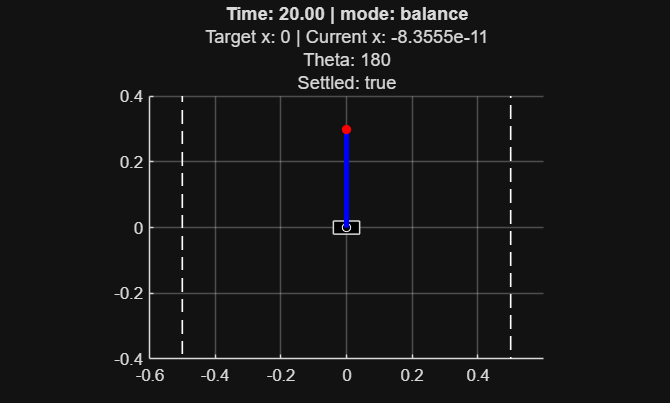

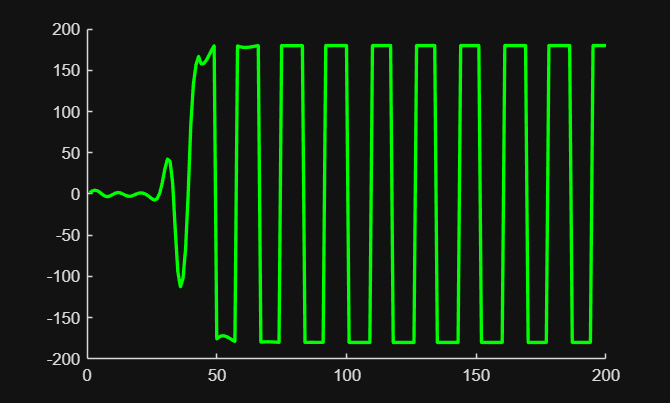

v = 0;
a = 0;

% Target position
target_theta = 180*pi/180;
target_x = 0;
target_start_x = 0;
target_E = g * (L/2);

% Setup
left_lim = plot([-(m/2) -(m/2)], [-1.5 1.5], 'w--', 'LineWidth', 1);
right_lim = plot([(m/2) (m/2)], [-1.5 1.5], 'w--', 'LineWidth', 1);
cart = rectangle("Position", [x-0.04 -0.02 0.08 0.04], "FaceColor", "k");
pivot = plot(0, 0, 'wo', 'MarkerSize', 5);
rod = plot([x, L*sin(theta)], [0, -L*cos(theta)], 'b-', 'LineWidth', 3);
bob = plot(x+L*sin(theta), -L*cos(theta), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'red');
mode = "reset";
set = false;

theta_error_sum = 0;
x_error_sum = 0;

N = 10;
counter = 0;
settled = false;
max_x = 0;
E = 0;
GPE = 0;

figure;
% ax_energy = gca;
% h = animatedline('Color', 'b', 'LineWidth', 2);
ax_theta = gca;
theta_graph = animatedline("Color", "G", "Linewidth", 2);

for i = 1:20/dt
    tic;

    mode = update_mode(mode, x, theta, target_start_x, E, g, L);

    KE = (1/2) * (1/3)*L^2 * omega^2;
    GPE = g * -(L/2)*cos(theta);
    E = KE + GPE;

    switch mode
        case "reset"
            a = 2*(target_start_x-x) - 2*v; % Reset position to x=0
        case "swingup"
            set = true;
            if abs(theta) <= 1e-3 && abs(omega) <= 1e-3
                a = 0.01;
            else
                E_error = target_E - E;
                alpha_adjust = 3.1 * max(E_error, 0.1*g*L) * omega * cos(theta); % Minimum E_error for near upright position
                
                a_swing = -(2*L)/(3*cos(theta)) * alpha_adjust;
                a_center = -5*x - 0.5*v;   % pulls cart back toward 0
                a = max(-max_accel, min(max_accel, a_swing + a_center));
            end
            
        case "balance"
            x_error = target_x - x;
            dtheta = Kp_x*(x_error) + Ki_x*x_error_sum + Kd_x*(-v);
            new_target_theta = mod(target_theta + dtheta + pi, 2*pi) - pi;
            theta_error = mod((new_target_theta - theta) + pi, 2*pi) - pi;
            alpha_adjust = Kp_theta*(theta_error) + Ki_theta*theta_error_sum + Kd_theta*(-omega);

            theta_error_sum = theta_error_sum + theta_error * dt;
            x_error_sum = x_error_sum + x_error * dt;

            if ~settled
                if abs(theta_error) < pi/180 && abs(x_error) < 0.01
                    counter = counter + 1;
                    if counter == N
                        settled = true;
                    end
                else
                    counter = 0;
                end
            end

            a = max(-max_accel, min(max_accel, -(2*L)/(3*cos(theta)) * alpha_adjust));
    end
    
    v = v + a * dt;
    x = x + v * dt;
    % x = 0;

    % % Boundaries
    if x <= -(m/2) || x >= (m/2)
        x = max(-(m/2), min((m/2), x));
        a = (0 - v) / dt;
        v = 0;
    end

    alpha = -3/(2*L)*(a*cos(theta) + g*sin(theta)) - b*omega;
    omega = omega + alpha * dt;
    theta = theta + omega * dt;
    pivot.XData = x;
    rod.XData = [x, x + L*sin(theta)];
    rod.YData = [0, -L*cos(theta)];
    bob.XData = x + L*sin(theta);
    bob.YData = -L*cos(theta);
    cart.Position = [x-0.04 -0.02 0.08 0.04];

    theta = mod(theta + pi, 2*pi) - pi;
    
    drawnow;
    
    elapsed = toc;
    remaining = dt - elapsed;
    if remaining > 0
        pause(remaining);
    end
    
    title(ax_anim, "Time: " + num2str(i*dt, '%.2f') + " | mode: " + mode);
    subtitle(ax_anim, ["Target x: " + target_x + " | Current x: " + x, "Theta: " + theta*180/pi, "Settled: " + settled]);
    % addpoints(h, i, GPE);
    addpoints(theta_graph, i, theta*180/pi);

end


%--------------------------------Functions------------------------------------%

% function mode = update_mode(x, theta, set)
%     theta_error_from_top = mod(pi - theta + pi, 2*pi) - pi;
%     if abs(theta_error_from_top) < (pi/180 * 25)
%         mode = "balance";
%     else
%         if (x > 0.03 || x < -0.03) && set == false
%             mode = "setpos";
%         else
%             mode = "swingup";
%         end
%     end
% end

function mode = update_mode(mode, x, theta, target_start_x, E, g, L)
    switch mode
        case "reset"
            if abs(target_start_x-x) < 0.02 && E < 0.0005 - g * (L/2)
                mode = "swingup";
            else
                mode = "reset";
            end
        case "swingup"
            theta_error_from_top = mod(pi - theta + pi, 2*pi) - pi;
                if abs(theta_error_from_top) < (pi/180 * 20)
                    mode = "balance";
                else
                    mode = "swingup";
                end
    end
end

